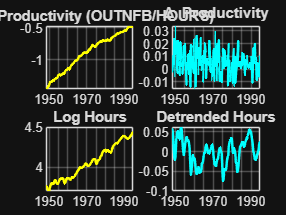

%% SECTION 1 — Load/ transform data (OUTNFB + HOANBS, 1948Q1–1994Q4)

clc; clear; close all;

outdir = 'output'; if ~exist(outdir,'dir'), mkdir(outdir); end
start_date = datetime(1948,1,1);
end_date   = datetime(1994,12,31);

%  HOURS (HOANBS: Nonfarm Business Sector Hours) 
Tn     = readtable('data/HOANBS.csv');
date_n = Tn{:,1}; 
val_n  = Tn{:,2};
dN     = datetime(string(date_n),'InputFormat','yyyy-MM-dd','Format','yyyyQQQ');
ttN    = timetable(dN,double(val_n)); 
ttN.Properties.VariableNames = {'HOURS'};
ttN    = retime(ttN,'quarterly','mean');

% OUTPUT (OUTNFB: Nonfarm Business Sector Real Output) 
To     = readtable('data/OUTNFB.csv');
date_o = To{:,1}; 
val_o  = To{:,2};
dO     = datetime(string(date_o),'InputFormat','yyyy-MM-dd','Format','yyyyQQQ');
ttO    = timetable(dO,double(val_o)); 
ttO.Properties.VariableNames = {'OUT'};
ttO    = retime(ttO,'quarterly','mean');

% Sync/ trim sample 
tt = synchronize(ttO, ttN, 'intersection');
tt = tt(timerange(start_date, end_date), :);
dates_all = tt.Properties.RowTimes;

% Logs calc
log_out   = log(tt.OUT);
log_hours = log(tt.HOURS);

% Productivity and hours
x = log_out - log_hours;   % productivity lvl
n = log_hours;             % hours lvl

%  First differences 
dx = [NaN; diff(x)];
dn = [NaN; diff(n)];

%  Linear detrend hours for Spec B 
Tidx = (1:numel(n))';
Xlin = [ones(size(Tidx)) Tidx];
b_lin = Xlin \ n;
n_tilde = n - (Xlin*b_lin);   % detended hours

%  Align all series (remove initial NaN) 
valid   = ~isnan(dx) & ~isnan(dn);
dates   = dates_all(valid);
dx      = dx(valid);
dn      = dn(valid);
n_tilde = n_tilde(valid);

%  Preview 
figure('Position',[100 100 800 600]);
subplot(2,2,1);
plot(dates, x(valid),'y','LineWidth',1.5); grid on;
title('Log Productivity (OUTNFB/HOURS)');
subplot(2,2,2);
plot(dates, dx,'c','LineWidth',1.5); grid on;
title('\Delta Productivity');
subplot(2,2,3);
plot(dates, n(valid),'y','LineWidth',1.5); grid on;
title('Log Hours');
subplot(2,2,4);
plot(dates, n_tilde,'c','LineWidth',1.5); grid on;
title('Detrended Hours');

saveas(gcf, fullfile(outdir,'data_preview_OUTNFB.png'));

%% SECTION 2 — Spec A VAR: Y = [Δx, Δn]  (lag selection + estimation)
% uses: dx, dn  

% settings for VAR
min_lags = 2;      
max_lags = 6;
include_const = true;

Y_A = [dx dn];         % T x 2
[T_A, K_A] = size(Y_A);

bestAIC = inf;
pA = min_lags;
A_A = []; Sigma_A = []; B_A = []; U_A = [];

for p = min_lags:max_lags
    % build regressors X and dependent Ydep
    Ydep = Y_A(p+1:T_A, :);           % (T-p) x K
    X = [];
    for i = 1:p
        X = [X, Y_A(p+1-i:T_A-i, :)]; % lag i for all vars
    end
    if include_const
        X = [X, ones(T_A-p,1)];
    end

    % OLS 
    B = X \ Ydep;                     % ((K*p)+const) x K
    U = Ydep - X*B;                   % residuals
    Sigma_u = (U'*U) / (size(U,1) - size(X,2));   % covariance of reduced-form shocks

    % AIC for VAR(p) 
    aic = log(det(Sigma_u)) + 2*size(B,1)*K_A/T_A;

    if aic < bestAIC
        bestAIC = aic;
        pA = p; B_A = B; U_A = U; Sigma_A = Sigma_u;

        % unpack B into A1..Ap (K x K x p)
        Atemp = zeros(K_A, K_A, p);
        row = 1;
        for ii = 1:p
            Atemp(:,:,ii) = B(row:row+K_A-1, :)';
            row = row + K_A;
        end
        A_A = Atemp;
    end
end

fprintf('Section 2 complete: Spec A selected p = %d lags.\n', pA);

Section 2 complete: Spec A selected p = 2 lags.


%% SECTION 3 — Spec B VAR: Y = [Δx, n~]  (lag selection + estimation)
% uses: dx, n_tilde  (from Section 1)
% outputs: pB, A_B (A1..Ap), Sigma_B, B_B (OLS coef), U_B (residuals), Y_B (data matrix)

% settings same as s2
min_lags = 2;
max_lags = 6;
include_const = true;

Y_B = [dx n_tilde];       % T x 2
[T_B, K_B] = size(Y_B);

bestAIC = inf;
pB = min_lags;
A_B = []; Sigma_B = []; B_B = []; U_B = [];

for p = min_lags:max_lags
    % build regressors X and dependent Ydep
    Ydep = Y_B(p+1:T_B, :);           % (T-p) x K
    X = [];
    for i = 1:p
        X = [X, Y_B(p+1-i:T_B-i, :)]; % lag i for all vars
    end
    if include_const
        X = [X, ones(T_B-p,1)];
    end

    % OLS 
    B = X \ Ydep;                     % ((K*p)+const) x K
    U = Ydep - X*B;                   % residuals
    Sigma_u = (U'*U) / (size(U,1) - size(X,2));   % reduced-form covariance

    % AIC for VAR
    aic = log(det(Sigma_u)) + 2*size(B,1)*K_B/T_B;

    if aic < bestAIC
        bestAIC = aic;
        pB = p; B_B = B; U_B = U; Sigma_B = Sigma_u;

        % unpack B into A1..Ap (K x K x p)
        Atemp = zeros(K_B, K_B, p);
        row = 1;
        for ii = 1:p
            Atemp(:,:,ii) = B(row:row+K_B-1, :)';
            row = row + K_B;
        end
        A_B = Atemp;
    end
end



%% SECTION 4 — Longrun identification for both specs (Galí 1999)
% Assumption: only the "technology shock" has a permanent effect on productivity.



%  Spec A 
K = size(A_A,1);
AsumA = eye(K);
for i = 1:pA
    AsumA = AsumA - A_A(:,:,i);
end
SA = inv(AsumA);                 
MA = SA * Sigma_A * SA';          

% robust Cholesky 
try
    LA = chol(MA, 'lower');
catch
    LA = chol(MA + 1e-12*eye(K), 'lower');
end

H_A = SA \ LA;                    % structural impact so that SA*H_A is lower triangular

disp('Spec A: long-run impact SA*H_A (should be lower triangular)'); 

Spec A: long-run impact SA*H_A (should be lower triangular)


disp(SA*H_A);

    0.0086         0
    0.0012    0.0151





%  Spec B 
K = size(A_B,1);
AsumB = eye(K);
for i = 1:pB
    AsumB = AsumB - A_B(:,:,i);
end
SB = inv(AsumB);
MB = SB * Sigma_B * SB';

try
    LB = chol(MB, 'lower');
catch
    LB = chol(MB + 1e-12*eye(K), 'lower');
end

H_B = SB \ LB;

disp('Spec B: long-run impact SB*H_B (should be lower triangular)'); 

Spec B: long-run impact SB*H_B (should be lower triangular)


disp(SB*H_B);

    0.0092    0.0000
   -0.0330    0.0858





%% SECTION 5 — Baseline IRFs with OUTNFB 

outdir = 'output'; if ~exist(outdir,'dir'), mkdir(outdir); end
horizons = 40; h = (0:horizons)';

% Guard: need dx, dn, n_tilde from Section 1 
if ~(exist('dx','var') && exist('dn','var') && exist('n_tilde','var'))
    error('Section 5 needs dx, dn, n_tilde from Section 1. Run Section 1 first.');
end

% SPEC A: Y = [Δx, Δn] 
Y_A = [dx(:) dn(:)]; [T_A,K] = size(Y_A);
bestAIC = Inf; pA = 2; A_A = []; Sigma_A = []; B_A = []; U_A = [];

for p = 2:6
    Ydep = Y_A(p+1:T_A,:);
    X = [];
    for i = 1:p, X = [X Y_A(p+1-i:T_A-i,:)]; end
    X = [X ones(T_A-p,1)];                % constant
    B = X\Ydep;                            % OLS
    U = Ydep - X*B;                        % residuals
    Sig = (U'*U) / (size(U,1) - size(X,2));
    aic = log(det(Sig)) + 2*size(B,1)*K/T_A;

    if aic < bestAIC
        bestAIC = aic; pA = p; Sigma_A = Sig; B_A = B; U_A = U;
        A_A = zeros(K,K,p);
        row = 1;
        for i = 1:p, A_A(:,:,i) = B(row:row+K-1,:)'; row = row + K; end
    end
end

% Long-run ID (Galí)
S = eye(K); for i=1:pA, S = S - A_A(:,:,i); end; S = inv(S);
M = S*Sigma_A*S';
[L,flag] = chol(M,'lower'); if flag~=0, [L,~] = chol(M + 1e-12*eye(K),'lower'); end
H_A = S\L;

% IRFs to technology shock (shock 1)
F = zeros(K*pA);
for i=1:pA-1, F((i*K+1):(i*K+K), ((i-1)*K+1):(i*K)) = eye(K); end
for i=1:pA,   F(1:K, ((i-1)*K+1):(i*K)) = A_A(:,:,i); end
J = [eye(K); zeros(K*(pA-1),K)];

IRF = zeros(horizons+1,K,K); IRF(1,:,:) = H_A;
Fpow = eye(K*pA);
for hh=1:horizons
    Fpow = Fpow*F;
    IRF(hh+1,:,:) = (J' * Fpow * J) * H_A;
end
irfA_tech = squeeze(IRF(:,:,1));   % (horizons+1) x 2

% SPEC B: Y = [Δx, n~]
Y_B = [dx(:) n_tilde(:)]; [T_B,K] = size(Y_B);
bestAIC = Inf; pB = 2; A_B = []; Sigma_B = []; B_B = []; U_B = [];

for p = 2:6
    Ydep = Y_B(p+1:T_B,:);
    X = [];
    for i = 1:p, X = [X Y_B(p+1-i:T_B-i,:)]; end
    X = [X ones(T_B-p,1)];
    B = X\Ydep;
    U = Ydep - X*B;
    Sig = (U'*U) / (size(U,1) - size(X,2));
    aic = log(det(Sig)) + 2*size(B,1)*K/T_B;

    if aic < bestAIC
        bestAIC = aic; pB = p; Sigma_B = Sig; B_B = B; U_B = U;
        A_B = zeros(K,K,p);
        row = 1;
        for i = 1:p, A_B(:,:,i) = B(row:row+K-1,:)'; row = row + K; end
    end
end

S = eye(K); for i=1:pB, S = S - A_B(:,:,i); end; S = inv(S);
M = S*Sigma_B*S';
[L,flag] = chol(M,'lower'); if flag~=0, [L,~] = chol(M + 1e-12*eye(K),'lower'); end
H_B = S\L;

F = zeros(K*pB);
for i=1:pB-1, F((i*K+1):(i*K+K), ((i-1)*K+1):(i*K)) = eye(K); end
for i=1:pB,   F(1:K, ((i-1)*K+1):(i*K)) = A_B(:,:,i); end
J = [eye(K); zeros(K*(pB-1),K)];

IRF = zeros(horizons+1,K,K); IRF(1,:,:) = H_B;
Fpow = eye(K*pB);
for hh=1:horizons
    Fpow = Fpow*F;
    IRF(hh+1,:,:) = (J' * Fpow * J) * H_B;
end
irfB_tech = squeeze(IRF(:,:,1));

% Save CSVs
writematrix([h irfA_tech], fullfile(outdir,'irf_specA_tech_OUTNFB.csv'));
writematrix([h irfB_tech], fullfile(outdir,'irf_specB_tech_OUTNFB.csv'));

try, writematrix([h irfA_tech], fullfile(outdir,'irf_specA_tech.csv')); end
try, writematrix([h irfB_tech], fullfile(outdir,'irf_specB_tech.csv')); end



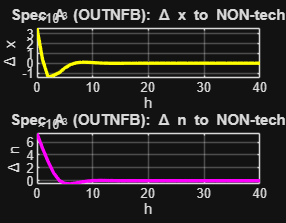

% SECTION 5N — IRFs to NON-technology shock 

outdir = 'output'; if ~exist(outdir,'dir'), mkdir(outdir); end
horizons = 40; h = (0:horizons)';

% Guard: need Section 5 objects
needA = exist('A_A','var') && exist('H_A','var') && exist('pA','var');
needB = exist('A_B','var') && exist('H_B','var') && exist('pB','var');
if ~needA || ~needB
    error('Run Section 5 first so A_A/H_A/pA and A_B/H_B/pB are in memory.');
end

%  Spec A (Y = [Δx, Δn]) 
K = size(A_A,1); p = pA;
F = zeros(K*p);
for i=1:p-1, F((i*K+1):(i*K+K), ((i-1)*K+1):(i*K)) = eye(K); end
for i=1:p,   F(1:K, ((i-1)*K+1):(i*K)) = A_A(:,:,i); end
J = [eye(K); zeros(K*(p-1),K)];

IRF = zeros(horizons+1,K,K); IRF(1,:,:) = H_A;
Fpow = eye(K*p);
for hh=1:horizons
    Fpow = Fpow * F;
    IRF(hh+1,:,:) = (J' * Fpow * J) * H_A;
end
irfA_nontech = squeeze(IRF(:,:,2));   % shock 2

% Plot/ save
figA_nt = figure; set(figA_nt,'Position',[120 120 720 560]);
subplot(2,1,1); plot(h, irfA_nontech(:,1),'y','LineWidth',2); grid on
xlabel('h'); ylabel('\Delta x'); title('Spec A (OUTNFB): \Delta x to NON-tech');
subplot(2,1,2); plot(h, irfA_nontech(:,2),'m','LineWidth',2); grid on
xlabel('h'); ylabel('\Delta n'); title('Spec A (OUTNFB): \Delta n to NON-tech');
saveas(figA_nt, fullfile(outdir,'irf_specA_nontech_OUTNFB.png'));

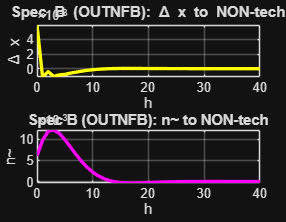

writematrix([h irfA_nontech], fullfile(outdir,'irf_specA_nontech_OUTNFB.csv'));

%  Spec B (Y = [Δx, n~]) 
K = size(A_B,1); p = pB;
F = zeros(K*p);
for i=1:p-1, F((i*K+1):(i*K+K), ((i-1)*K+1):(i*K)) = eye(K); end
for i=1:p,   F(1:K, ((i-1)*K+1):(i*K)) = A_B(:,:,i); end
J = [eye(K); zeros(K*(p-1),K)];

IRF = zeros(horizons+1,K,K); IRF(1,:,:) = H_B;
Fpow = eye(K*p);
for hh=1:horizons
    Fpow = Fpow * F;
    IRF(hh+1,:,:) = (J' * Fpow * J) * H_B;
end
irfB_nontech = squeeze(IRF(:,:,2));

figB_nt = figure; set(figB_nt,'Position',[140 140 720 560]);
subplot(2,1,1); plot(h, irfB_nontech(:,1),'y','LineWidth',2); grid on
xlabel('h'); ylabel('\Delta x'); title('Spec B (OUTNFB): \Delta x to NON-tech');
subplot(2,1,2); plot(h, irfB_nontech(:,2),'m','LineWidth',2); grid on
xlabel('h'); ylabel('n~'); title('Spec B (OUTNFB): n~ to NON-tech');
saveas(figB_nt, fullfile(outdir,'irf_specB_nontech_OUTNFB.png'));

writematrix([h irfB_nontech], fullfile(outdir,'irf_specB_nontech_OUTNFB.csv'));




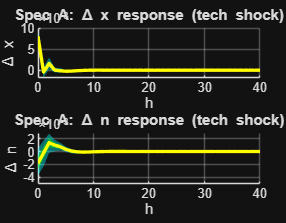

%% SECTION 6 — Bootstrap confidence bands (68% and 95%) for tech-shock IRFs
% uses: Y_A, U_A, B_A, A_A, Sigma_A, pA;  Y_B, U_B, B_B, A_B, Sigma_B, pB

% settings for bootstrap
n_boot      = 500;          % increase to 1000+ for final results
ci_levels   = [0.68, 0.95]; % we'll compute 68% and 95% percentile bands
include_const = true;       
horizons    = 40;           
h           = (0:horizons)';




% SPEC A BOOTSTRAP
T_A = size(Y_A,1);
K_A = size(Y_A,2);
storeA = nan(horizons+1, K_A, n_boot);   % only shock 1 responses, K=2 variables

for b = 1:n_boot
    % 1) resample residuals
    idx = randi(size(U_A,1), size(U_A,1), 1);
    Ub  = U_A(idx,:);

    % 2) generate bootstrap sample Yb using original coefficients B_A
    Yb = Y_A;                   
    for t = pA+1:T_A
        ylag = [];
        for L = 1:pA
            ylag = [ylag, Yb(t-L,:)];
        end
        if include_const
            ylag = [ylag, 1]; 
        end
        Yb(t,:) = ylag * B_A + Ub(t-pA,:);
    end

    % 3) restimate VAR on Yb 
    Ydepb = Yb(pA+1:T_A, :);
    Xb = [];
    for i = 1:pA
        Xb = [Xb, Yb(pA+1-i:T_A-i, :)];
    end
    if include_const
        Xb = [Xb, ones(T_A-pA,1)];
    end
    Bb   = Xb \ Ydepb;
    Ub2  = Ydepb - Xb*Bb;
    Sigb = (Ub2'*Ub2) / (size(Ub2,1) - size(Xb,2));

    % 4) unpack Bb into Ab
    Ab = zeros(K_A, K_A, pA);
    row = 1;
    for ii = 1:pA
        Ab(:,:,ii) = Bb(row:row+K_A-1,: )';
        row = row + K_A;
    end

    % 5) long run identification on bootstrap draw: Hb
    Asum = eye(K_A);
    for ii = 1:pA, Asum = Asum - Ab(:,:,ii); end
    Sb = inv(Asum);
    Mb = Sb * Sigb * Sb';
    try
        Lb = chol(Mb,'lower');
    catch
        Lb = chol(Mb + 1e-12*eye(K_A),'lower');
    end
    Hb = Sb \ Lb;

    % 6) IRFs via companion form 
    F = zeros(K_A*pA);
    for ii=1:pA-1
        F((ii*K_A+1):(ii*K_A+K_A), ((ii-1)*K_A+1):(ii*K_A)) = eye(K_A);
    end
    for ii=1:pA
        F(1:K_A, ((ii-1)*K_A+1):(ii*K_A)) = Ab(:,:,ii);
    end
    J = [eye(K_A); zeros(K_A*(pA-1),K_A)];
    IRF_all = zeros(horizons+1, K_A, K_A);
    IRF_all(1,:,:) = Hb;
    Fpow = eye(K_A*pA);
    for hh=1:horizons
        Fpow = Fpow*F;
        IRF_all(hh+1,:,:) = (J'*Fpow*J)*Hb;
    end

    % 7) store responses to tech shock (shock 1)
    storeA(:,:,b) = squeeze(IRF_all(:,:,1));
end

% percentile bands for Spec A
lo68_A = prctile(storeA, 100*(1-0.68)/2, 3);
hi68_A = prctile(storeA, 100*(1+0.68)/2, 3);
lo95_A = prctile(storeA, 100*(1-0.95)/2, 3);
hi95_A = prctile(storeA, 100*(1+0.95)/2, 3);

% recompute baseline once here (reuse A_A,H_A)
K_A = size(A_A,1);
F = zeros(K_A*pA);
for ii=1:pA-1
    F((ii*K_A+1):(ii*K_A+K_A), ((ii-1)*K_A+1):(ii*K_A)) = eye(K_A);
end
for ii=1:pA
    F(1:K_A, ((ii-1)*K_A+1):(ii*K_A)) = A_A(:,:,ii);
end
J = [eye(K_A); zeros(K_A*(pA-1),K_A)];
IRF_A_base = zeros(horizons+1, K_A, K_A);
IRF_A_base(1,:,:) = H_A;
Fpow = eye(K_A*pA);
for hh=1:horizons
    Fpow = Fpow*F;
    IRF_A_base(hh+1,:,:) = (J'*Fpow*J)*H_A;
end
irfA_tech = squeeze(IRF_A_base(:,:,1));

% plot Spec A with bands
figA = figure('Position',[120 120 720 560]);
subplot(2,1,1); hold on
patch([h; flipud(h)], [lo95_A(:,1); flipud(hi95_A(:,1))], [0 1 1], 'EdgeColor','none','FaceAlpha',0.4); % cyan
patch([h; flipud(h)], [lo68_A(:,1); flipud(hi68_A(:,1))], [0 1 0], 'EdgeColor','none','FaceAlpha',0.4); % green
plot(h, irfA_tech(:,1),'y','LineWidth',2); % yellow line
grid on; xlabel('h'); ylabel('\Delta x'); title('Spec A: \Delta x response (tech shock)');

subplot(2,1,2); hold on
patch([h; flipud(h)], [lo95_A(:,2); flipud(hi95_A(:,2))], [0 1 1], 'EdgeColor','none','FaceAlpha',0.4);
patch([h; flipud(h)], [lo68_A(:,2); flipud(hi68_A(:,2))], [0 1 0], 'EdgeColor','none','FaceAlpha',0.4);
plot(h, irfA_tech(:,2),'y','LineWidth',2);
grid on; xlabel('h'); ylabel('\Delta n'); title('Spec A: \Delta n response (tech shock)');
saveas(figA, fullfile(outdir,'irf_specA_tech_bands.png'));

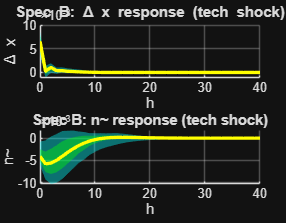



% save CSV for Spec A bands
writematrix([h, irfA_tech, lo68_A, hi68_A, lo95_A, hi95_A], fullfile(outdir,'irf_specA_tech_with_bands.csv'));


% SPEC B BOOTSTRAP
T_B = size(Y_B,1);
K_B = size(Y_B,2);
storeB = nan(horizons+1, K_B, n_boot);

for b = 1:n_boot
    idx = randi(size(U_B,1), size(U_B,1), 1);
    Ub  = U_B(idx,:);

    Yb = Y_B;
    for t = pB+1:T_B
        ylag = [];
        for L = 1:pB
            ylag = [ylag, Yb(t-L,:)]; 
        end
        if include_const
            ylag = [ylag, 1]; 
        end
        Yb(t,:) = ylag * B_B + Ub(t-pB,:);
    end

    Ydepb = Yb(pB+1:T_B, :);
    Xb = [];
    for i = 1:pB
        Xb = [Xb, Yb(pB+1-i:T_B-i, :)]; 
    end
    if include_const
        Xb = [Xb, ones(T_B-pB,1)];
    end
    Bb   = Xb \ Ydepb;
    Ub2  = Ydepb - Xb*Bb;
    Sigb = (Ub2'*Ub2) / (size(Ub2,1) - size(Xb,2));

    Ab = zeros(K_B, K_B, pB);
    row = 1;
    for ii = 1:pB
        Ab(:,:,ii) = Bb(row:row+K_B-1,: )';
        row = row + K_B;
    end

    Asum = eye(K_B);
    for ii = 1:pB, Asum = Asum - Ab(:,:,ii); end
    Sb = inv(Asum);
    Mb = Sb * Sigb * Sb';
    try
        Lb = chol(Mb,'lower');
    catch
        Lb = chol(Mb + 1e-12*eye(K_B),'lower');
    end
    Hb = Sb \ Lb;

    F = zeros(K_B*pB);
    for ii=1:pB-1
        F((ii*K_B+1):(ii*K_B+K_B), ((ii-1)*K_B+1):(ii*K_B)) = eye(K_B);
    end
    for ii=1:pB
        F(1:K_B, ((ii-1)*K_B+1):(ii*K_B)) = Ab(:,:,ii);
    end
    J = [eye(K_B); zeros(K_B*(pB-1),K_B)];
    IRF_all = zeros(horizons+1, K_B, K_B);
    IRF_all(1,:,:) = Hb;
    Fpow = eye(K_B*pB);
    for hh=1:horizons
        Fpow = Fpow*F;
        IRF_all(hh+1,:,:) = (J'*Fpow*J)*Hb;
    end

    storeB(:,:,b) = squeeze(IRF_all(:,:,1));
end

lo68_B = prctile(storeB, 100*(1-0.68)/2, 3);
hi68_B = prctile(storeB, 100*(1+0.68)/2, 3);
lo95_B = prctile(storeB, 100*(1-0.95)/2, 3);
hi95_B = prctile(storeB, 100*(1+0.95)/2, 3);

K_B = size(A_B,1);
F = zeros(K_B*pB);
for ii=1:pB-1
    F((ii*K_B+1):(ii*K_B+K_B), ((ii-1)*K_B+1):(ii*K_B)) = eye(K_B);
end
for ii=1:pB
    F(1:K_B, ((ii-1)*K_B+1):(ii*K_B)) = A_B(:,:,ii);
end
J = [eye(K_B); zeros(K_B*(pB-1),K_B)];
IRF_B_base = zeros(horizons+1, K_B, K_B);
IRF_B_base(1,:,:) = H_B;
Fpow = eye(K_B*pB);
for hh=1:horizons
    Fpow = Fpow*F;
    IRF_B_base(hh+1,:,:) = (J'*Fpow*J)*H_B;
end
irfB_tech = squeeze(IRF_B_base(:,:,1));

figB = figure('Position',[140 140 720 560]);
subplot(2,1,1); hold on
patch([h; flipud(h)], [lo95_B(:,1); flipud(hi95_B(:,1))], [0 1 1], 'EdgeColor','none','FaceAlpha',0.4);
patch([h; flipud(h)], [lo68_B(:,1); flipud(hi68_B(:,1))], [0 1 0], 'EdgeColor','none','FaceAlpha',0.4);
plot(h, irfB_tech(:,1),'y','LineWidth',2);
grid on; xlabel('h'); ylabel('\Delta x'); title('Spec B: \Delta x response (tech shock)');

subplot(2,1,2); hold on
patch([h; flipud(h)], [lo95_B(:,2); flipud(hi95_B(:,2))], [0 1 1], 'EdgeColor','none','FaceAlpha',0.4);
patch([h; flipud(h)], [lo68_B(:,2); flipud(hi68_B(:,2))], [0 1 0], 'EdgeColor','none','FaceAlpha',0.4);
plot(h, irfB_tech(:,2),'y','LineWidth',2);
grid on; xlabel('h'); ylabel('n~'); title('Spec B: n~ response (tech shock)');
saveas(figB, fullfile(outdir,'irf_specB_tech_bands.png'));



writematrix([h, irfB_tech, lo68_B, hi68_B, lo95_B, hi95_B], fullfile(outdir,'irf_specB_tech_with_bands.csv'));



%% SECTION 7 — Conditional corellations tech v nontech
%   Spec A: Y_A, U_A, A_A, H_A, pA
%   Spec B: Y_B, U_B, A_B, H_B, pB




% truncation for MA representation
L = 40;              
% horizons for IRF builder reuse
horizons = L;


K = size(A_A,1); p = pA;
F = zeros(K*p);
for ii=1:p-1
    F((ii*K+1):(ii*K+K), ((ii-1)*K+1):(ii*K)) = eye(K);
end
for ii=1:p
    F(1:K, ((ii-1)*K+1):(ii*K)) = A_A(:,:,ii);
end
J = [eye(K); zeros(K*(p-1),K)];
PhiA = cell(L+1,1);
PhiA{1} = H_A;
Fpow = eye(K*p);
for j=1:L
    Fpow = Fpow*F;
    PhiA{j+1} = (J' * Fpow * J) * H_A;
end

% SPEC B
K = size(A_B,1); p = pB;
F = zeros(K*p);
for ii=1:p-1
    F((ii*K+1):(ii*K+K), ((ii-1)*K+1):(ii*K)) = eye(K);
end
for ii=1:p
    F(1:K, ((ii-1)*K+1):(ii*K)) = A_B(:,:,ii);
end
J = [eye(K); zeros(K*(p-1),K)];
PhiB = cell(L+1,1);
PhiB{1} = H_B;
Fpow = eye(K*p);
for j=1:L
    Fpow = Fpow*F;
    PhiB{j+1} = (J' * Fpow * J) * H_B;
end

% Recover structural shocks e_t from reduced-form residuals U (u_t = H e_t)

% SPEC A
T_eff_A = size(U_A,1);      % corresponds to Y_A(pA+1 : end , :)
eA = zeros(T_eff_A, 2);
for t=1:T_eff_A
    eA(t,:)= (H_A \ U_A(t,:)')';  % row vector
end

% SPEC B
T_eff_B = size(U_B,1);
eB = zeros(T_eff_B, 2);
for t=1:T_eff_B
    eB(t,:)= (H_B \ U_B(t,:)')';
end

% Build component series via convolution with Phi_j

% SPEC A components
compA_tech    = zeros(T_eff_A, 2);  
compA_nontech = zeros(T_eff_A, 2);
for t=1:T_eff_A
    Jmax = min(L, t-1);
    accT = [0;0]; accN = [0;0];
    for j=0:Jmax
        vT = [eA(t-j,1); 0];
        vN = [0; eA(t-j,2)];
        accT = accT + PhiA{j+1} * vT;
        accN = accN + PhiA{j+1} * vN;
    end
    compA_tech(t,:)    = accT';
    compA_nontech(t,:) = accN';
end

% SPEC B components
compB_tech    = zeros(T_eff_B, 2);   
compB_nontech = zeros(T_eff_B, 2);
for t=1:T_eff_B
    Jmax = min(L, t-1);
    accT = [0;0]; accN = [0;0];
    for j=0:Jmax
        vT = [eB(t-j,1); 0];
        vN = [0; eB(t-j,2)];
        accT = accT + PhiB{j+1} * vT;
        accN = accN + PhiB{j+1} * vN;
    end
    compB_tech(t,:)    = accT';
    compB_nontech(t,:) = accN';
end

% Correlations between components of variable 1 and 2
% Spec A: corr between (Δx component) and (Δn component)
corr_tech_A    = corr( compA_tech(:,1),    compA_tech(:,2),    'rows','pairwise' );
corr_nontech_A = corr( compA_nontech(:,1), compA_nontech(:,2), 'rows','pairwise' );

% Spec B: corr between (Δx component) and (n~ component)
corr_tech_B    = corr( compB_tech(:,1),    compB_tech(:,2),    'rows','pairwise' );
corr_nontech_B = corr( compB_nontech(:,1), compB_nontech(:,2), 'rows','pairwise' );

fprintf('Spec A  (Δx, Δn):   corr(tech) = %+0.3f,   corr(non-tech) = %+0.3f\n', corr_tech_A, corr_nontech_A);

Spec A  (Δx, Δn):   corr(tech) = -0.620,   corr(non-tech) = +0.576


fprintf('Spec B  (Δx, n~):   corr(tech) = %+0.3f,   corr(non-tech) = %+0.3f\n', corr_tech_B, corr_nontech_B);

Spec B  (Δx, n~):   corr(tech) = -0.470,   corr(non-tech) = -0.112



% Save to CSV
Tcorr = table(corr_tech_A, corr_nontech_A, corr_tech_B, corr_nontech_B);
Tcorr.Properties.VariableNames = {'corr_tech_A','corr_nontech_A','corr_tech_B','corr_nontech_B'};
writetable(Tcorr, fullfile(outdir,'conditional_correlations.csv'));




%% SECTION 7B — Table 1 & 2 style correlations for Specs A and B

% Unconditional
uncorr_A = corr(Y_A(:,1), Y_A(:,2), 'Rows','pairwise');      % corr(Δx, Δn)
uncorr_B = corr(Y_B(:,1), Y_B(:,2), 'Rows','pairwise');      % corr(Δx, n~)



% Pack and save 
T1 = [uncorr_A, corr_tech_A,    corr_nontech_A;   % Panel A (Spec A)
      uncorr_B, corr_tech_B,    corr_nontech_B];  % Panel B (Spec B)

csvwrite(fullfile(outdir,'table1_table2_correlations.csv'), T1);

T1

T1 =     0.1088   -0.6197    0.5765
   -0.2279   -0.4696   -0.1117


%% SECTION 7C — Bootstrap SEs & 95% CIs for correlation tables 

outdir = 'output'; if ~exist(outdir,'dir'), mkdir(outdir); end

n_boot = 500;          % use 1000+ if time allows
Lma    = 40;           % MA truncation for components
include_const = true;  % must match earlier estimation

% SPEC A
T = size(Y_A,1); K = size(Y_A,2); p = pA;

uncA = zeros(n_boot,1);   % unconditional corr(Δx,Δn)
tecA = zeros(n_boot,1);   % corr of tech components
nonA = zeros(n_boot,1);   % corr of non-tech components

for b = 1:n_boot
    % 1) residual bootstrap (resample U_A rows)
    idx = randi(size(U_A,1), size(U_A,1), 1);
    Ub  = U_A(idx,:);
    Yb  = Y_A;

    % simulate forward using estiated coefficients B_A
    for t = p+1:T
        ylag = [];
        for L=1:p, ylag = [ylag, Yb(t-L,:)]; end
        if include_const, ylag = [ylag, 1]; end
        Yb(t,:) = ylag * B_A + Ub(t-p,:);
    end

    % 2) restimate VAR on Yb
    Ydep = Yb(p+1:T,:);  X = [];
    for i=1:p, X = [X, Yb(p+1-i:T-i,:)]; end
    if include_const, X = [X, ones(T-p,1)]; end
    Bb = X\Ydep;  Ub2 = Ydep - X*Bb;
    Sig = (Ub2'*Ub2) / (size(Ub2,1) - size(X,2));

    % unpack Ab
    Ab = zeros(K,K,p); row=1;
    for i=1:p, Ab(:,:,i) = Bb(row:row+K-1,:)'; row = row + K; end

    % 3) long-run ID
    S = eye(K); for i=1:p, S = S - Ab(:,:,i); end; S = inv(S);
    M = S*Sig*S'; [Lc,flag] = chol(M,'lower'); if flag~=0, [Lc,~]=chol(M+1e-12*eye(K),'lower'); end
    Hb = S\Lc;

    % 4) structural shocks on effective sample
    Teff = size(Ub2,1);
    eb = zeros(Teff,K);
    for t=1:Teff, eb(t,:) = (Hb \ Ub2(t,:)')'; end

    % 5) build MA coefficients Phi{0..Lma}
    F = zeros(K*p);
    for ii=1:p-1, F((ii*K+1):(ii*K+K), ((ii-1)*K+1):(ii*K)) = eye(K); end
    for ii=1:p,   F(1:K, ((ii-1)*K+1):(ii*K)) = Ab(:,:,ii); end
    J = [eye(K); zeros(K*(p-1),K)];
    Phi = cell(Lma+1,1); Phi{1} = Hb;   % j=0
    Fpow = eye(K*p);
    for j=1:Lma
        Fpow = Fpow * F;
        Phi{j+1} = (J' * Fpow * J) * Hb;
    end

    % 6) tech / non-tech components
    compT = zeros(Teff, K);
    compN = zeros(Teff, K);
    for t=1:Teff
        Jmax = min(Lma, t-1);
        accT = [0;0]; accN = [0;0];
        for j=0:Jmax
            accT = accT + Phi{j+1} * [eb(t-j,1); 0];
            accN = accN + Phi{j+1} * [0; eb(t-j,2)];
        end
        compT(t,:) = accT';
        compN(t,:) = accN';
    end

    % 7) correlations for this bootstrap draw
    uncA(b) = corr(Yb(:,1), Yb(:,2), 'Rows','pairwise');
    tecA(b) = corr(compT(:,1), compT(:,2), 'Rows','pairwise');
    nonA(b) = corr(compN(:,1), compN(:,2), 'Rows','pairwise');
end

% SPEC B
T = size(Y_B,1); K = size(Y_B,2); p = pB;

uncB = zeros(n_boot,1);
tecB = zeros(n_boot,1);
nonB = zeros(n_boot,1);

for b = 1:n_boot
    idx = randi(size(U_B,1), size(U_B,1), 1);
    Ub  = U_B(idx,:);
    Yb  = Y_B;

    for t = p+1:T
        ylag = [];
        for L=1:p, ylag = [ylag, Yb(t-L,:)]; end
        if include_const, ylag = [ylag, 1]; end
        Yb(t,:) = ylag * B_B + Ub(t-p,:);
    end

    Ydep = Yb(p+1:T,:);  X = [];
    for i=1:p, X = [X, Yb(p+1-i:T-i,:)]; end
    if include_const, X = [X, ones(T-p,1)]; end
    Bb = X\Ydep;  Ub2 = Ydep - X*Bb;
    Sig = (Ub2'*Ub2) / (size(Ub2,1) - size(X,2));

    Ab = zeros(K,K,p); row=1;
    for i=1:p, Ab(:,:,i) = Bb(row:row+K-1,:)'; row = row + K; end

    S = eye(K); for i=1:p, S = S - Ab(:,:,i); end; S = inv(S);
    M = S*Sig*S'; [Lc,flag] = chol(M,'lower'); if flag~=0, [Lc,~]=chol(M+1e-12*eye(K),'lower'); end
    Hb = S\Lc;

    Teff = size(Ub2,1);
    eb = zeros(Teff,K);
    for t=1:Teff, eb(t,:) = (Hb \ Ub2(t,:)')'; end

    F = zeros(K*p);
    for ii=1:p-1, F((ii*K+1):(ii*K+K), ((ii-1)*K+1):(ii*K)) = eye(K); end
    for ii=1:p,   F(1:K, ((ii-1)*K+1):(ii*K)) = Ab(:,:,ii); end
    J = [eye(K); zeros(K*(p-1),K)];
    Phi = cell(Lma+1,1); Phi{1} = Hb;
    Fpow = eye(K*p);
    for j=1:Lma, Fpow = Fpow*F; Phi{j+1} = (J' * Fpow * J) * Hb; end

    compT = zeros(Teff, K);
    compN = zeros(Teff, K);
    for t=1:Teff
        Jmax = min(Lma, t-1);
        accT = [0;0]; accN = [0;0];
        for j=0:Jmax
            accT = accT + Phi{j+1} * [eb(t-j,1); 0];
            accN = accN + Phi{j+1} * [0; eb(t-j,2)];
        end
        compT(t,:) = accT';
        compN(t,:) = accN';
    end

    uncB(b) = corr(Yb(:,1), Yb(:,2), 'Rows','pairwise');
    tecB(b) = corr(compT(:,1), compT(:,2), 'Rows','pairwise');
    nonB(b) = corr(compN(:,1), compN(:,2), 'Rows','pairwise');
end

% Summaries & save
% point estimates from baseline (already in memory)
uncorr_A_hat = corr(Y_A(:,1), Y_A(:,2), 'Rows','pairwise');
uncorr_B_hat = corr(Y_B(:,1), Y_B(:,2), 'Rows','pairwise');


se_uncA  = std(uncA);  ci_uncA  = prctile(uncA,  [2.5 97.5]);
se_tecA  = std(tecA);  ci_tecA  = prctile(tecA,  [2.5 97.5]);
se_nonA  = std(nonA);  ci_nonA  = prctile(nonA,  [2.5 97.5]);

se_uncB  = std(uncB);  ci_uncB  = prctile(uncB,  [2.5 97.5]);
se_tecB  = std(tecB);  ci_tecB  = prctile(tecB,  [2.5 97.5]);
se_nonB  = std(nonB);  ci_nonB  = prctile(nonB,  [2.5 97.5]);

Tcorr = [ ...
  uncorr_A_hat, se_uncA, ci_uncA(1), ci_uncA(2),  corr_tech_A, se_tecA, ci_tecA(1), ci_tecA(2),  corr_nontech_A, se_nonA, ci_nonA(1), ci_nonA(2); ...
  uncorr_B_hat, se_uncB, ci_uncB(1), ci_uncB(2),  corr_tech_B, se_tecB, ci_tecB(1), ci_tecB(2),  corr_nontech_B, se_nonB, ci_nonB(1), ci_nonB(2) ...
];

% fallback if writematrix is missing (ChatGPT helped me with this)
try
    writematrix(Tcorr, fullfile(outdir,'table_correlations_bootstrap.csv'));
catch
    csvwrite(fullfile(outdir,'table_correlations_bootstrap.csv'), Tcorr);
end

disp('Section 7C complete: saved SEs/CIs to output/table_correlations_bootstrap.csv');

Section 7C complete: saved SEs/CIs to output/table_correlations_bootstrap.csv


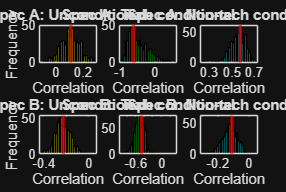

%% Plot bootstrap distributions of correlations (Spec A & B)

figCorr = figure; set(figCorr,'Position',[100 100 900 600]);

% Spec A
subplot(2,3,1);
histogram(uncA,30,'FaceColor','y','EdgeColor','k');
title('Spec A: Unconditional'); xlabel('Correlation'); ylabel('Frequency');
xline(uncorr_A_hat,'r','LineWidth',2);

subplot(2,3,2);
histogram(tecA,30,'FaceColor','g','EdgeColor','k');
title('Spec A: Tech conditional'); xlabel('Correlation');
xline(corr_tech_A,'r','LineWidth',2);

subplot(2,3,3);
histogram(nonA,30,'FaceColor','c','EdgeColor','k');
title('Spec A: Non-tech conditional'); xlabel('Correlation');
xline(corr_nontech_A,'r','LineWidth',2);

% Spec B
subplot(2,3,4);
histogram(uncB,30,'FaceColor','y','EdgeColor','k');
title('Spec B: Unconditional'); xlabel('Correlation'); ylabel('Frequency');
xline(uncorr_B_hat,'r','LineWidth',2);

subplot(2,3,5);
histogram(tecB,30,'FaceColor','g','EdgeColor','k');
title('Spec B: Tech conditional'); xlabel('Correlation');
xline(corr_tech_B,'r','LineWidth',2);

subplot(2,3,6);
histogram(nonB,30,'FaceColor','c','EdgeColor','k');
title('Spec B: Non-tech conditional'); xlabel('Correlation');
xline(corr_nontech_B,'r','LineWidth',2);

saveas(figCorr, fullfile(outdir,'bootstrap_correlations_hist.png'));

%% SECTION 8 — Historical decomposition 
% Align everything to the effective VAR sample length 

fprintf('Computing historical decomposition for Spec A...\n');

Computing historical decomposition for Spec A...


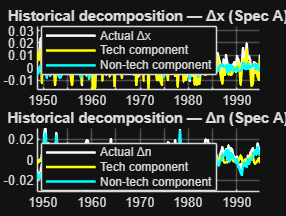


K = size(A_A,1);
T_A      = size(Y_A,1);          % total rows in Y_A
T_eff_A  = size(U_A,1);          % = T_A - pA
dates_hd = dates(pA+1:end);     
actual   = Y_A(pA+1:end,:);      % T_eff_A x 2

% Structural shocks
eA = zeros(T_eff_A, K);
for t = 1:T_eff_A
    eA(t,:) = (H_A \ U_A(t,:)')';
end

% Build MA representation coefficients Phi_j 
L = 40;                                    % number of lags
F = zeros(K*pA);
for ii = 1:pA-1
    F((ii*K+1):(ii*K+K), ((ii-1)*K+1):(ii*K)) = eye(K);
end
for ii = 1:pA
    F(1:K, ((ii-1)*K+1):(ii*K)) = A_A(:,:,ii);
end
J = [eye(K); zeros(K*(pA-1),K)];
PhiA = cell(L+1,1);
PhiA{1} = H_A;
Fpow = eye(K*pA);
for j = 1:L
    Fpow = Fpow * F;
    PhiA{j+1} = (J' * Fpow * J) * H_A;
end

% Reconstruct contributions 
compA_tech    = zeros(T_eff_A, 2);   
compA_nontech = zeros(T_eff_A, 2);
for t = 1:T_eff_A
    Jmax = min(L, t-1);
    accT = [0;0]; accN = [0;0];
    for j = 0:Jmax
        vT = [eA(t-j,1); 0];
        vN = [0; eA(t-j,2)];
        accT = accT + PhiA{j+1} * vT;
        accN = accN + PhiA{j+1} * vN;
    end
    compA_tech(t,:)    = accT';
    compA_nontech(t,:) = accN';
end

% Plot: actual vs tech and nontech comps
figHD = figure('Position',[100 100 820 620]);
subplot(2,1,1); hold on
plot(dates_hd, actual(:,1),'w','LineWidth',1.5);
plot(dates_hd, compA_tech(:,1),'y','LineWidth',1.5);
plot(dates_hd, compA_nontech(:,1),'c','LineWidth',1.5);
legend({'Actual Δx','Tech component','Non-tech component'},'Location','best');
title('Historical decomposition — Δx (Spec A)'); grid on;

subplot(2,1,2); hold on
plot(dates_hd, actual(:,2),'w','LineWidth',1.5);
plot(dates_hd, compA_tech(:,2),'y','LineWidth',1.5);
plot(dates_hd, compA_nontech(:,2),'c','LineWidth',1.5);
legend({'Actual Δn','Tech component','Non-tech component'},'Location','best');
title('Historical decomposition — Δn (Spec A)'); grid on;

saveas(figHD, fullfile(outdir,'historical_decomp_specA.png'));


% Save numeric outputs
writematrix([datenum(dates_hd), actual, compA_tech, compA_nontech], ...
    fullfile(outdir,'historical_decomp_specA.csv'));



%% SECTION 9 — Historical decomposition (Spec B, Δx and n~)

fprintf('Computing historical decomposition for Spec B...\n');

Computing historical decomposition for Spec B...


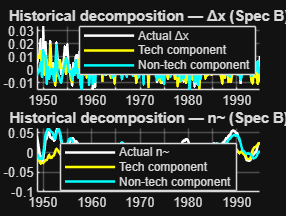


K = size(A_B,1);
T_B      = size(Y_B,1);
T_eff_B  = size(U_B,1);          % = T_B - pB
dates_hdB = dates(pB+1:end);     % alignment
actualB   = Y_B(pB+1:end,:);     

% Structural shocks: e_t = H^{-1} u_t 
eB = zeros(T_eff_B, K);
for t = 1:T_eff_B
    eB(t,:) = (H_B \ U_B(t,:)')';
end

% Build MA representation coeficients Phi_j 
L = 40;                                 
F = zeros(K*pB);
for ii = 1:pB-1
    F((ii*K+1):(ii*K+K), ((ii-1)*K+1):(ii*K)) = eye(K);
end
for ii = 1:pB
    F(1:K, ((ii-1)*K+1):(ii*K)) = A_B(:,:,ii);
end
J = [eye(K); zeros(K*(pB-1),K)];
PhiB = cell(L+1,1);
PhiB{1} = H_B;
Fpow = eye(K*pB);
for j = 1:L
    Fpow = Fpow * F;
    PhiB{j+1} = (J' * Fpow * J) * H_B;
end

% Reconstruct contributions
compB_tech    = zeros(T_eff_B, 2);  
compB_nontech = zeros(T_eff_B, 2);
for t = 1:T_eff_B
    Jmax = min(L, t-1);
    accT = [0;0]; accN = [0;0];
    for j = 0:Jmax
        vT = [eB(t-j,1); 0];      % tech shock only
        vN = [0; eB(t-j,2)];      % non-tech shock only
        accT = accT + PhiB{j+1} * vT;
        accN = accN + PhiB{j+1} * vN;
    end
    compB_tech(t,:)    = accT';
    compB_nontech(t,:) = accN';
end

% Plot 
figHDB = figure('Position',[110 110 820 620]);
subplot(2,1,1); hold on
plot(dates_hdB, actualB(:,1),'w','LineWidth',1.5);
plot(dates_hdB, compB_tech(:,1),'y','LineWidth',1.5);
plot(dates_hdB, compB_nontech(:,1),'c','LineWidth',1.5);
legend({'Actual Δx','Tech component','Non-tech component'},'Location','best');
title('Historical decomposition — Δx (Spec B)'); grid on;

subplot(2,1,2); hold on
plot(dates_hdB, actualB(:,2),'w','LineWidth',1.5);
plot(dates_hdB, compB_tech(:,2),'y','LineWidth',1.5);
plot(dates_hdB, compB_nontech(:,2),'c','LineWidth',1.5);
legend({'Actual n~','Tech component','Non-tech component'},'Location','best');
title('Historical decomposition — n~ (Spec B)'); grid on;

saveas(figHDB, fullfile(outdir,'historical_decomp_specB.png'));


% Save numeric outputs
writematrix([datenum(dates_hdB), actualB, compB_tech, compB_nontech], ...
    fullfile(outdir,'historical_decomp_specB.csv'));




%% SECTION 10 — Diagnostics: stability & residual checks
K = size(A_A,1); p = pA; F = zeros(K*p);
for i=1:p-1, F((i*K+1):(i*K+K), ((i-1)*K+1):(i*K))=eye(K); end
for i=1:p,   F(1:K, ((i-1)*K+1):(i*K))=A_A(:,:,i); end
fprintf('Spec A stability max |root| = %.3f\n', max(abs(eig(F))));

Spec A stability max |root| = 0.640


K = size(A_B,1); p = pB; F = zeros(K*p);
for i=1:p-1, F((i*K+1):(i*K+K), ((i-1)*K+1):(i*K))=eye(K); end
for i=1:p,   F(1:K, ((i-1)*K+1):(i*K))=A_B(:,:,i); end
fprintf('Spec B stability max |root| = %.3f\n', max(abs(eig(F))));

Spec B stability max |root| = 0.779



% residual autocorr (trace of lag-L corr^2)
T = size(U_A,1); for L=1:4
    r=corr(U_A(1+L:end,:),U_A(1:end-L,:)); fprintf('Spec A, L=%d trace(r''r)=%.3f\n',L,trace(r'*r));
end

Spec A, L=1 trace(r'r)=0.003
Spec A, L=2 trace(r'r)=0.013
Spec A, L=3 trace(r'r)=0.032
Spec A, L=4 trace(r'r)=0.008


T = size(U_B,1); for L=1:4
    r=corr(U_B(1+L:end,:),U_B(1:end-L,:)); fprintf('Spec B, L=%d trace(r''r)=%.3f\n',L,trace(r'*r));
end

Spec B, L=1 trace(r'r)=0.020
Spec B, L=2 trace(r'r)=0.001
Spec B, L=3 trace(r'r)=0.038
Spec B, L=4 trace(r'r)=0.003



%% SECTION 11 — Lag robustness (Spec A, p=2..6) 

horizons=40; h=(0:horizons)'; results=[];
for p=2:6
    Y=Y_A; [T,K]=size(Y);
    Ydep=Y(p+1:T,:); X=[]; for i=1:p, X=[X Y(p+1-i:T-i,:)]; end; X=[X ones(T-p,1)];
    B=X\Ydep; U=Ydep-X*B; Sig=(U'*U)/(size(U,1)-size(X,2));
    A=zeros(K,K,p); row=1; for i=1:p, A(:,:,i)=B(row:row+K-1,:)'; row=row+K; end
    S=eye(K); for i=1:p, S=S-A(:,:,i); end; S=inv(S);
    M=S*Sig*S'; L=chol(M,'lower'); H=S\L;
    F=zeros(K*p);
    for i=1:p-1, F((i*K+1):(i*K+K), ((i-1)*K+1):(i*K))=eye(K); end
    for i=1:p,   F(1:K, ((i-1)*K+1):(i*K))=A(:,:,i); end
    J=[eye(K); zeros(K*(p-1),K)];
    IRF=zeros(horizons+1,K,K); IRF(1,:,:)=H; Fpow=eye(K*p);
    for hh=1:horizons, Fpow=Fpow*F; IRF(hh+1,:,:)=(J'*Fpow*J)*H; end
    tech=squeeze(IRF(:,:,1));
    [minval,minidx]=min(tech(:,2));
    results=[results; p, tech(1,2), minval, minidx-1]; 
end
Trob = array2table(results);
Trob.Properties.VariableNames = {'p','h0_hours','min_hours','h_at_min'};
disp(Trob);

    p     h0_hours     min_hours     h_at_min
    _    __________    __________    ________

    2    -0.0018153    -0.0018153       0    
    3     -0.002542     -0.002542       0    
    4    -0.0023064    -0.0023064       0    
    5    -0.0029755    -0.0029755       0    
    6     -0.002918     -0.002918       0    



writetable(Trob, fullfile(outdir,'robustness_lags_specA.csv'));


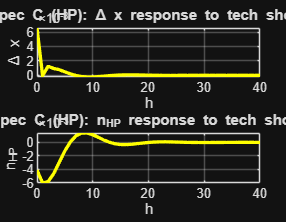

%% SECTION 12 — HP-detrended hours extension (Spec C)



lambda = 1600;
Tn = length(n);
m  = Tn - 2;                             % rows of 2nd-diff operator
D  = spdiags([ones(m,1) -2*ones(m,1) ones(m,1)], [0 1 2], m, Tn);
I  = speye(Tn);
Hhp = I + lambda*(D'*D);                 % SPD; solves HP filter
n_trend = Hhp \ n;
n_cycle = n - n_trend;                   % HP-cycle of hours (level)

% 2) Align to VAR sample & build Y = [Δx, n_HP] 
Y_C = [dx, n_cycle(valid)];             
Tc  = size(Y_C,1); Kc = 2;

% 3) VAR lag selection by AIC (p = 2..6)
bestAIC = Inf; pC = 2;
AC = zeros(Kc,Kc,2); SigmaC = eye(Kc);
p = 2;
while p <= 6
    Ydep = Y_C(p+1:Tc, :);
    X = [];
    i = 1;
    while i <= p
        X = [X, Y_C(p+1-i:Tc-i, :)];
        i = i + 1;
    end
    X = [X, ones(Tc-p,1)];              % constant
    B = X \ Ydep;
    U = Ydep - X*B;
    dof = size(U,1) - size(X,2);
    Sig = (U'*U) / dof;
    aic = log(det(Sig)) + 2*size(B,1)*Kc/Tc;

    if aic < bestAIC
        bestAIC = aic; pC = p; SigmaC = Sig;
        AC = zeros(Kc,Kc,p);
        row = 1; ii = 1;
        while ii <= p
            AC(:,:,ii) = B(row:row+Kc-1, :)';
            row = row + Kc; ii = ii + 1;
        end
    end
    p = p + 1;
end

%  4) Long-run identification (Galí) 
S = eye(Kc);
ii = 1;
while ii <= pC
    S = S - AC(:,:,ii);
    ii = ii + 1;
end
S = inv(S);
M = S * SigmaC * S';
% robust Cholesky (lower)
[LL,flag] = chol(M, 'lower');
if flag ~= 0
    [LL,~] = chol(M + 1e-12*eye(Kc), 'lower');
end
HC = S \ LL;

% 5) IRFs to technology shock (shock 1)
horizons = 40;  h = (0:horizons)';
F = zeros(Kc*pC);
ii = 1;
while ii <= pC-1
    F((ii*Kc+1):(ii*Kc+Kc), ((ii-1)*Kc+1):(ii*Kc)) = eye(Kc);
    ii = ii + 1;
end
ii = 1;
while ii <= pC
    F(1:Kc, ((ii-1)*Kc+1):(ii*Kc)) = AC(:,:,ii);
    ii = ii + 1;
end
J = [eye(Kc); zeros(Kc*(pC-1), Kc)];

IRF = zeros(horizons+1, Kc, Kc);
IRF(1,:,:) = HC;
Fpow = eye(Kc*pC);
hh = 1;
while hh <= horizons
    Fpow = Fpow * F;
    IRF(hh+1,:,:) = (J' * Fpow * J) * HC;
    hh = hh + 1;
end
techC = squeeze(IRF(:,:,1));             % responses to tech shock

% 6) Plot 
figC = figure;
set(figC,'Position',[120 120 720 560]);

subplot(2,1,1);
plot(h, techC(:,1), 'y', 'LineWidth', 2);
grid on; xlabel('h'); ylabel('\Delta x'); title('Spec C (HP): \Delta x response to tech shock');

subplot(2,1,2);
plot(h, techC(:,2), 'y', 'LineWidth', 2);
grid on; xlabel('h'); ylabel('n_{HP}'); title('Spec C (HP): n_{HP} response to tech shock');

% Save figure 
saveas(figC, fullfile(outdir,'irf_specC_HP_tech.png'));

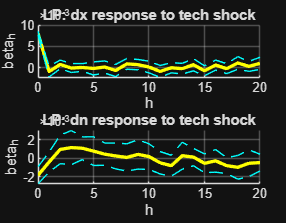

%% SECTION 13 — Local Projections robust

outdir = 'output'; if ~exist(outdir,'dir'), mkdir(outdir); end

% Align 
T_eff = size(U_A,1);
Yeff  = Y_A(pA+1:end,:);          % T_eff x 2 : [dx, dn]

% Structural tech shocks e1 from Spec A
e1 = zeros(T_eff,1);
for t = 1:T_eff
    tmp = H_A \ U_A(t,:)';
    e1(t) = tmp(1);
end

% Precompute pA lags of Y and e1
pZ = pA;
YL = cell(pZ,1);
SL = cell(pZ,1);
for L = 1:pZ
    YL{L} = [NaN(L,2); Yeff(1:end-L,:)];
    SL{L} = [NaN(L,1); e1(1:end-L)];
end

Hmax = 20;
beta = NaN(Hmax+1,2);
seNW = NaN(Hmax+1,2);

for hstep = 0:Hmax
    Yh = Yeff(1+hstep:end,:);      % dependent y_{t+h}
    sh = e1(1:end-hstep);          % shock at t
    Tz = size(Yh,1);

    % build controls Z_t
    Z = [];
    for L = 1:pZ
        Z = [Z, YL{L}(1:Tz,:), SL{L}(1:Tz,:)];  % cotcat lags
    end

    % drop first pZ rows 
    keep = (pZ+1):Tz;
    Yh = Yh(keep,:);
    sh = sh(keep,:);
    Z  = Z(keep,:);

 
    X = [ones(length(keep),1) sh Z];

    % OLS per variable with very plain Newey–West HAC
    for k = 1:2
        y = Yh(:,k);
        b = X\y;
        beta(hstep+1,k) = b(2);

        res = y - X*b;
        Tn = length(res);
        bw = round(sqrt(Tn));            % bandwidth

        S = (X.*res)'*(X.*res);
        for ell = 1:bw
            w = 1 - ell/(bw+1);
            S = S + w * ( (X(1+ell:end,:).*res(1+ell:end))' * (X(1:end-ell,:).*res(1:end-ell)) ...
                        + (X(1:end-ell,:).*res(1:end-ell))' * (X(1+ell:end,:).*res(1+ell:end)) );
        end

        XtX = X'*X;
        V = inv(XtX) * S * inv(XtX);
        seNW(hstep+1,k) = sqrt(V(2,2));
    end
end

% Plot 
h = (0:Hmax)';
figLP = figure;
set(figLP,'Position',[120 120 720 560]);

subplot(2,1,1); hold on
p1 = plot(h, beta(:,1), 'y-');     set(p1,'LineWidth',2);
p2 = plot(h, beta(:,1)+1.96*seNW(:,1), 'c--');
p3 = plot(h, beta(:,1)-1.96*seNW(:,1), 'c--');
grid on; xlabel('h'); ylabel('beta_h'); title('LP: dx response to tech shock');

subplot(2,1,2); hold on
p4 = plot(h, beta(:,2), 'y-');     set(p4,'LineWidth',2);
p5 = plot(h, beta(:,2)+1.96*seNW(:,2), 'c--');
p6 = plot(h, beta(:,2)-1.96*seNW(:,2), 'c--');
grid on; xlabel('h'); ylabel('beta_h'); title('LP: dn response to tech shock');

saveas(figLP, fullfile(outdir,'lp_specA_tech.png'));


% Save CSV 
try
    writematrix([h beta seNW], fullfile(outdir,'lp_specA_tech.csv'));
catch
    csvwrite(fullfile(outdir,'lp_specA_tech.csv'), [h beta seNW]);
end



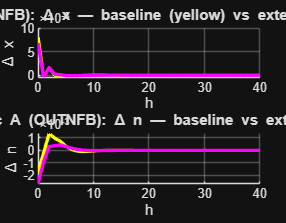

%% SECTION 14 Extended sample with OUTNFB 

outdir = 'output'; if ~exist(outdir,'dir'), mkdir(outdir); end
horizons = 40; h = (0:horizons)';

%  HOURS 
Tn     = readtable('data/HOANBS.csv');
date_n = Tn{:,1}; val_n = Tn{:,2};
dN     = datetime(string(date_n),'InputFormat','yyyy-MM-dd','Format','yyyyQQQ');
ttN    = timetable(dN,double(val_n)); 
ttN.Properties.VariableNames = {'HOURS'};
ttN    = retime(ttN,'quarterly','mean');

%  OUTPUT (OUTNFB) 
To     = readtable('data/OUTNFB.csv');
date_o = To{:,1}; val_o = To{:,2};
dO     = datetime(string(date_o),'InputFormat','yyyy-MM-dd','Format','yyyyQQQ');
ttO    = timetable(dO,double(val_o)); 
ttO.Properties.VariableNames = {'OUT'};
ttO    = retime(ttO,'quarterly','mean');

%  Sync & trim extended sample 
tt = synchronize(ttO, ttN, 'intersection');
tt = tt(timerange(datetime(1948,1,1), datetime(2019,12,31)), :);

log_out   = log(tt.OUT);
log_hours = log(tt.HOURS);

x2 = log_out - log_hours;
n2 = log_hours;

dx2 = [NaN; diff(x2)];
dn2 = [NaN; diff(n2)];

% Linear detrend hours
Tidx2 = (1:numel(n2))';
Xlin2 = [ones(size(Tidx2)) Tidx2];
b_lin2 = Xlin2 \ n2;
n_tilde2 = n2 - (Xlin2*b_lin2);

valid2   = ~isnan(dx2) & ~isnan(dn2);
dx2      = dx2(valid2);
dn2      = dn2(valid2);
n_tilde2 = n_tilde2(valid2);

%  Spec A (dx, dn) 
Y_A2 = [dx2 dn2]; [T2,K2] = size(Y_A2);
bestAIC = Inf; pA2 = 2; A_A2=[]; Sigma_A2=[]; B_A2=[];

for p = 2:6
    Ydep = Y_A2(p+1:T2,:); X = [];
    for i=1:p, X=[X Y_A2(p+1-i:T2-i,:)]; end
    X = [X ones(T2-p,1)];
    B = X\Ydep; U = Ydep - X*B;
    Sig = (U'*U)/(size(U,1)-size(X,2));
    aic = log(det(Sig)) + 2*size(B,1)*K2/T2;
    if aic < bestAIC
        bestAIC = aic; pA2=p; Sigma_A2=Sig; B_A2=B;
        A_A2=zeros(K2,K2,p); row=1;
        for i=1:p, A_A2(:,:,i)=B(row:row+K2-1,:)'; row=row+K2; end
    end
end
S = eye(K2); for i=1:pA2, S = S - A_A2(:,:,i); end; S=inv(S);
M = S*Sigma_A2*S'; [L,flag] = chol(M,'lower'); if flag~=0, [L,~]=chol(M+1e-12*eye(K2),'lower'); end
H_A2 = S\L;

F=zeros(K2*pA2);
for i=1:pA2-1, F((i*K2+1):(i*K2+K2),((i-1)*K2+1):(i*K2))=eye(K2); end
for i=1:pA2,   F(1:K2,((i-1)*K2+1):(i*K2))=A_A2(:,:,i); end
J=[eye(K2); zeros(K2*(pA2-1),K2)];
IRF_A2=zeros(horizons+1,K2,K2); IRF_A2(1,:,:)=H_A2; Fpow=eye(K2*pA2);
for hh=1:horizons, Fpow=Fpow*F; IRF_A2(hh+1,:,:)=(J'*Fpow*J)*H_A2; end
irfA2 = squeeze(IRF_A2(:,:,1));
writematrix([h irfA2], fullfile(outdir,'irf_specA_tech_OUTNFB_extended.csv'));

%  Spec B (dx, detrended n) 
Y_B2 = [dx2 n_tilde2]; [T2,K2] = size(Y_B2);
bestAIC=Inf; pB2=2; A_B2=[]; Sigma_B2=[]; B_B2=[];

for p = 2:6
    Ydep=Y_B2(p+1:T2,:); X=[];
    for i=1:p, X=[X Y_B2(p+1-i:T2-i,:)]; end
    X=[X ones(T2-p,1)];
    B=X\Ydep; U=Ydep-X*B; Sig=(U'*U)/(size(U,1)-size(X,2));
    aic=log(det(Sig))+2*size(B,1)*K2/T2;
    if aic<bestAIC
        bestAIC=aic; pB2=p; Sigma_B2=Sig; B_B2=B;
        A_B2=zeros(K2,K2,p); row=1;
        for i=1:p, A_B2(:,:,i)=B(row:row+K2-1,:)'; row=row+K2; end
    end
end
S=eye(K2); for i=1:pB2, S=S-A_B2(:,:,i); end; S=inv(S);
M=S*Sigma_B2*S'; [L,flag]=chol(M,'lower'); if flag~=0, [L,~]=chol(M+1e-12*eye(K2),'lower'); end
H_B2=S\L;

F=zeros(K2*pB2);
for i=1:pB2-1, F((i*K2+1):(i*K2+K2),((i-1)*K2+1):(i*K2))=eye(K2); end
for i=1:pB2,   F(1:K2,((i-1)*K2+1):(i*K2))=A_B2(:,:,i); end
J=[eye(K2); zeros(K2*(pB2-1),K2)];
IRF_B2=zeros(horizons+1,K2,K2); IRF_B2(1,:,:)=H_B2; Fpow=eye(K2*pB2);
for hh=1:horizons, Fpow=Fpow*F; IRF_B2(hh+1,:,:)=(J'*Fpow*J)*H_B2; end
irfB2 = squeeze(IRF_B2(:,:,1));
writematrix([h irfB2], fullfile(outdir,'irf_specB_tech_OUTNFB_extended.csv'));

%  Overlay extended v basline 
try
    A0 = readmatrix(fullfile(outdir,'irf_specA_tech_OUTNFB.csv'));
    B0 = readmatrix(fullfile(outdir,'irf_specB_tech_OUTNFB.csv'));
catch
    disp('Baseline OUTNFB CSVs missing — run Sections 1–5 first!');
    return
end

% Spec A overlay
figA = figure; set(figA,'Position',[120 120 720 560]);
subplot(2,1,1); hold on
p1=plot(A0(:,1),A0(:,2),'y-'); set(p1,'LineWidth',2);
p2=plot(h,irfA2(:,1),'m-'); set(p2,'LineWidth',2);
grid on; xlabel('h'); ylabel('\Delta x');
title('Spec A (OUTNFB): \Delta x — baseline (yellow) vs extended (magenta)');

subplot(2,1,2); hold on
p3=plot(A0(:,1),A0(:,3),'y-'); set(p3,'LineWidth',2);
p4=plot(h,irfA2(:,2),'m-'); set(p4,'LineWidth',2);
grid on; xlabel('h'); ylabel('\Delta n');
title('Spec A (OUTNFB): \Delta n — baseline vs extended');

saveas(figA, fullfile(outdir,'overlay_specA_OUTNFB_baseline_vs_extended.png'));

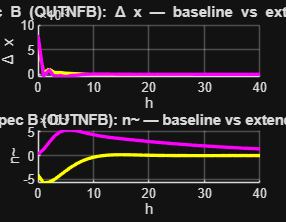


% Spec B overlay
figB = figure; set(figB,'Position',[140 140 720 560]);
subplot(2,1,1); hold on
p5=plot(B0(:,1),B0(:,2),'y-'); set(p5,'LineWidth',2);
p6=plot(h,irfB2(:,1),'m-'); set(p6,'LineWidth',2);
grid on; xlabel('h'); ylabel('\Delta x');
title('Spec B (OUTNFB): \Delta x — baseline vs extended');

subplot(2,1,2); hold on
p7=plot(B0(:,1),B0(:,3),'y-'); set(p7,'LineWidth',2);
p8=plot(h,irfB2(:,2),'m-'); set(p8,'LineWidth',2);
grid on; xlabel('h'); ylabel('n~');
title('Spec B (OUTNFB): n~ — baseline vs extended');

saveas(figB, fullfile(outdir,'overlay_specB_OUTNFB_baseline_vs_extended.png'));

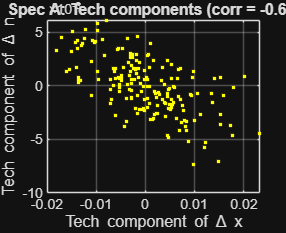

%% SECTION 15 — Plots

% Tech components (Spec A)
rT = corr(compA_tech(:,1), compA_tech(:,2), 'Rows','pairwise');
figF1T = figure; set(figF1T,'Position',[120 120 640 520]);
plot(compA_tech(:,1), compA_tech(:,2), '.', 'Color',[1 1 0]); grid on
xlabel('Tech component of \Delta x'); ylabel('Tech component of \Delta n');
title(['Spec A: Tech components (corr = ', num2str(rT,'%0.2f'), ')']);
saveas(figF1T, fullfile(outdir,'figure1_scatter_tech_specA.png'));

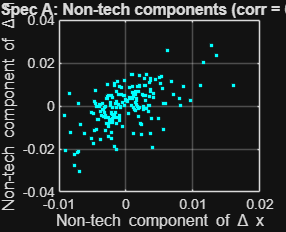


% Non-tech components (Spec A)
rN = corr(compA_nontech(:,1), compA_nontech(:,2), 'Rows','pairwise');
figF1N = figure; set(figF1N,'Position',[120 120 640 520]);
plot(compA_nontech(:,1), compA_nontech(:,2), '.', 'Color',[0 1 1]); grid on
xlabel('Non-tech component of \Delta x'); ylabel('Non-tech component of \Delta n');
title(['Spec A: Non-tech components (corr = ', num2str(rN,'%0.2f'), ')']);
saveas(figF1N, fullfile(outdir,'figure1_scatter_nontech_specA.png'));

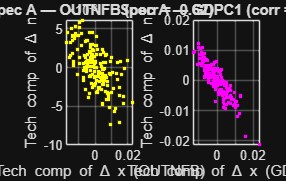

%% SECTION 17 — Copare OUTNFB vs GDPC1

outdir = 'output'; if ~exist(outdir,'dir'), mkdir(outdir); end
start_date = datetime(1948,1,1);
end_date   = datetime(1994,12,31);
horizons = 40; Lma = 40;    % IRF horizon and MA truncation

%  Load HOURS
Tn2   = readtable('data/HOANBS.csv');
dN2   = datetime(string(Tn2{:,1}),'InputFormat','yyyy-MM-dd','Format','yyyyQQQ');
ttN2  = timetable(dN2,double(Tn2{:,2}));
ttN2.Properties.VariableNames = {'HOURS'};
ttN2  = retime(ttN2,'quarterly','mean');

%  OUTNFB block 
To2   = readtable('data/OUTNFB.csv');
dO2   = datetime(string(To2{:,1}),'InputFormat','yyyy-MM-dd','Format','yyyyQQQ');
ttO2  = timetable(dO2,double(To2{:,2}));
ttO2.Properties.VariableNames = {'OUT'};
ttO2  = retime(ttO2,'quarterly','mean');
ttO2  = synchronize(ttO2, ttN2, 'intersection');
ttO2  = ttO2(timerange(start_date,end_date), :);

x_o = log(ttO2.OUT) - log(ttO2.HOURS);
n_o = log(ttO2.HOURS);
dx_o = [NaN; diff(x_o)];
dn_o = [NaN; diff(n_o)];
valid_o = ~isnan(dx_o) & ~isnan(dn_o);
Y_O = [dx_o(valid_o) dn_o(valid_o)];           % Spec A: [Δx, Δn]

%  GDPC1 block 
Ty2   = readtable('data/GDPC1.csv');
dY2   = datetime(string(Ty2{:,1}),'InputFormat','yyyy-MM-dd','Format','yyyyQQQ');
ttY2  = timetable(dY2,double(Ty2{:,2}));
ttY2.Properties.VariableNames = {'GDP'};
ttY2  = retime(ttY2,'quarterly','mean');
ttY2  = synchronize(ttY2, ttN2, 'intersection');
ttY2  = ttY2(timerange(start_date,end_date), :);

x_g = log(ttY2.GDP) - log(ttY2.HOURS);
n_g = log(ttY2.HOURS);
dx_g = [NaN; diff(x_g)];
dn_g = [NaN; diff(n_g)];
valid_g = ~isnan(dx_g) & ~isnan(dn_g);
Y_G = [dx_g(valid_g) dn_g(valid_g)];           % Spec A: [Δx, Δn]


% OUTNFB
[T_ok,K] = size(Y_O);
bestAIC = Inf; pO = 2; A_O = []; Sig_O = []; B_O = []; U_O = [];
for p=2:6
    Ydep = Y_O(p+1:T_ok,:); X=[];
    for i=1:p, X=[X Y_O(p+1-i:T_ok-i,:)]; end
    X=[X ones(T_ok-p,1)];
    B = X\Ydep; U = Ydep - X*B;
    Sig = (U'*U)/(size(U,1)-size(X,2));
    aic = log(det(Sig)) + 2*size(B,1)*K/T_ok;
    if aic<bestAIC
        bestAIC=aic; pO=p; Sig_O=Sig; B_O=B; U_O=U;
        A_O=zeros(K,K,p); row=1;
        for i=1:p, A_O(:,:,i)=B(row:row+K-1,:)'; row=row+K; end
    end
end
S = eye(K); for i=1:pO, S=S-A_O(:,:,i); end; S=inv(S);
M = S*Sig_O*S'; [L,flag]=chol(M,'lower'); if flag~=0, [L,~]=chol(M+1e-12*eye(K),'lower'); end
H_O = S\L;

% Structural shocks
Teff_O = size(U_O,1);
eO = zeros(Teff_O,K); for t=1:Teff_O, eO(t,:) = (H_O \ U_O(t,:)')'; end
F = zeros(K*pO);
for i=1:pO-1, F((i*K+1):(i*K+K),((i-1)*K+1):(i*K))=eye(K); end
for i=1:pO,   F(1:K,((i-1)*K+1):(i*K))=A_O(:,:,i); end
J = [eye(K); zeros(K*(pO-1),K)];
PhiO = cell(Lma+1,1); PhiO{1} = H_O; Fpow = eye(K*pO);
for j=1:Lma, Fpow=Fpow*F; PhiO{j+1}=(J'*Fpow*J)*H_O; end

compT_O = zeros(Teff_O,K);
for t=1:Teff_O
    Jmax = min(Lma,t-1); acc = [0;0];
    for j=0:Jmax, acc = acc + PhiO{j+1} * [eO(t-j,1); 0]; end
    compT_O(t,:) = acc';
end
corrTech_OUTNFB = corr(compT_O(:,1), compT_O(:,2), 'Rows','pairwise');

% GDPC1 
[T_g,K] = size(Y_G);
bestAIC = Inf; pG = 2; A_G = []; Sig_G = []; B_G = []; U_G = [];
for p=2:6
    Ydep = Y_G(p+1:T_g,:); X=[];
    for i=1:p, X=[X Y_G(p+1-i:T_g-i,:)]; end
    X=[X ones(T_g-p,1)];
    B = X\Ydep; U = Ydep - X*B;
    Sig = (U'*U)/(size(U,1)-size(X,2));
    aic = log(det(Sig)) + 2*size(B,1)*K/T_g;
    if aic<bestAIC
        bestAIC=aic; pG=p; Sig_G=Sig; B_G=B; U_G=U;
        A_G=zeros(K,K,p); row=1;
        for i=1:p, A_G(:,:,i)=B(row:row+K-1,:)'; row=row+K; end
    end
end
S = eye(K); for i=1:pG, S=S-A_G(:,:,i); end; S=inv(S);
M = S*Sig_G*S'; [L,flag]=chol(M,'lower'); if flag~=0, [L,~]=chol(M+1e-12*eye(K),'lower'); end
H_G = S\L;

Teff_G = size(U_G,1);
eG = zeros(Teff_G,K); for t=1:Teff_G, eG(t,:) = (H_G \ U_G(t,:)')'; end
F = zeros(K*pG);
for i=1:pG-1, F((i*K+1):(i*K+K),((i-1)*K+1):(i*K))=eye(K); end
for i=1:pG,   F(1:K,((i-1)*K+1):(i*K))=A_G(:,:,i); end
J = [eye(K); zeros(K*(pG-1),K)];
PhiG = cell(Lma+1,1); PhiG{1} = H_G; Fpow = eye(K*pG);
for j=1:Lma, Fpow=Fpow*F; PhiG{j+1}=(J'*Fpow*J)*H_G; end

compT_G = zeros(Teff_G,K);
for t=1:Teff_G
    Jmax = min(Lma,t-1); acc = [0;0];
    for j=0:Jmax, acc = acc + PhiG{j+1} * [eG(t-j,1); 0]; end
    compT_G(t,:) = acc';
end
corrTech_GDPC1 = corr(compT_G(:,1), compT_G(:,2), 'Rows','pairwise');

%  Plot
figC = figure; set(figC,'Position',[110 110 820 520]);

subplot(1,2,1);
plot(compT_O(:,1), compT_O(:,2), '.', 'Color',[1 1 0]); grid on
xlabel('Tech comp of \Delta x (OUTNFB)'); ylabel('Tech comp of \Delta n');
title(['Spec A — OUTNFB (corr = ', num2str(corrTech_OUTNFB,'%.2f'), ')']);

subplot(1,2,2);
plot(compT_G(:,1), compT_G(:,2), '.', 'Color',[1 0 1]); grid on
xlabel('Tech comp of \Delta x (GDPC1)'); ylabel('Tech comp of \Delta n');
title(['Spec A — GDPC1 (corr = ', num2str(corrTech_GDPC1,'%.2f'), ')']);

saveas(figC, fullfile(outdir,'compare_tech_scatter_OUTNFB_vs_GDPC1.png'));


%  Save csv 
C = {'OUTNFB', corrTech_OUTNFB; 'GDPC1', corrTech_GDPC1};
fid = fopen(fullfile(outdir,'compare_tech_corr_OUTNFB_vs_GDPC1.csv'),'w');
fprintf(fid,'Dataset,TechComponentCorrelation\n');
fprintf(fid,'%s,%.6f\n', C{1,1}, C{1,2});
fprintf(fid,'%s,%.6f\n', C{2,1}, C{2,2});
fclose(fid);


